# Assessment 1A Fibonacci seq 

Todd Backlaw H00368671

**Task 1**: Create a MATLAB function, fibonacci.m, that uses a FOR loop to produce a vector containing the first n Fibonacci numbers. (set n equal to number of months for part 2)

clc %clear console
clear %clear stored items

%number of months
n = 12;

%initialize array
fibonacci_seq = zeros(1, n);

%initalize first two fibonacci numbers 
fibonacci_seq(1) = 1;
fibonacci_seq(2) = 1;

%set up for loop to iterate through fib numbers 3 to 12 and calculate the
%fibonacci seq
for i = 3:n 

    fibonacci_seq(i) = fibonacci_seq(i - 1) + fibonacci_seq(i - 2); 

end 


**Notes of items used: **initialize variable, initialize array, index array, for loop with array index and calculations.

**Task 2**: Plot the total number of rabbits as a function of month, i.e. plot the first twelve Fibonacci numbers.

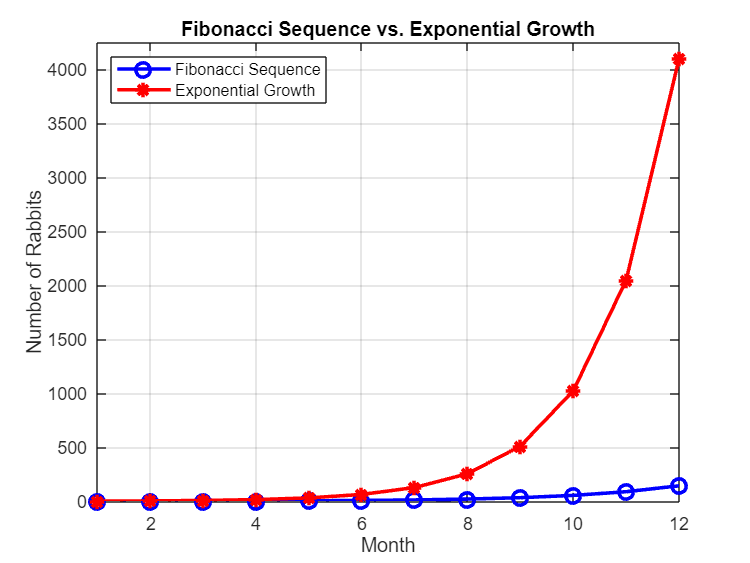

%initalize months variable 
months = 1:n;

%set up a population that doubles every month
pop = 2 .^ months;


% Plot the Fibonacci sequence

plot(months, fibonacci_seq, 'b-o', 'LineWidth', 2, 'MarkerSize', 8); 

hold on; 


% Plot the exponential growth

plot(months, pop, 'r-*', 'LineWidth', 2, 'MarkerSize', 8); 

hold off; 

% Adding labels and legend 

xlabel('Month');  

grid on

box on

xlim([1, 12]);

ylim([0, 4250]);

ylabel('Number of Rabbits');  

title('Fibonacci Sequence vs. Exponential Growth'); 

legend('Fibonacci Sequence', 'Exponential Growth', 'Location', 'Northwest');

**Notes on items used**: initialze array with stored variable, new variable using operators on another stored variable, plotting function with additions like linewidth etc, holds, plot housekeeping (labels, legend etc)

## Overview:

As seen in the figure above the exponential function grows to be much larger than the fibonacci function within the 12 month period. As predicted the exponential population growth exhibited an exponential trend on the plot where the fibonacci sequance was less aggresive.